A6.7（`如何利用嵌套函数实现无参泛函中的参数传递`）实时脚本

由张志涌编写、修改于 2023.1。

+++++++++++++++++++++++ 
正确配用方法 （8)
无参调用格式 ZAfzerotx(fH,x12) 中，表述目标函数的
第一输入量是内嵌套函数exmA6_5/objFun的具名句柄 fH=@objFun
所得搜索结果如下：
  零点位置为         3.6372
  该点处的函数值为   3.1086e-15
+++++++++++++++++++++++ 
正确配用方法 （9)
无参调用格式 ZAfzerotx(fH,x12) 中，表述目标函数的
第一输入量是内嵌套函数的含输入句柄fH= @(x)objFun(x)
所得搜索结果如下：
  零点位置为         3.6372
  该点处的函数值为   3.1086e-15


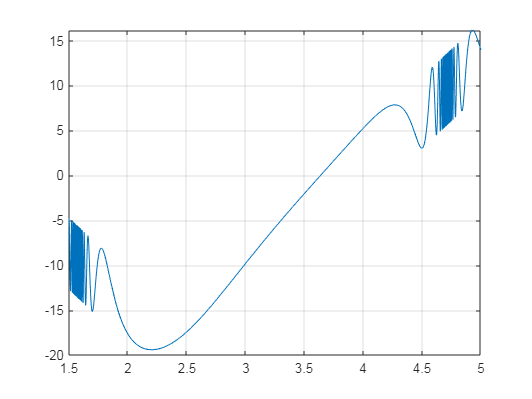

k1=4;k2=10;                 % k1,k2	是表述目标函数时所需的变参
exmA6_5(k1,k2);

function exmA6_5(k1,k2)
% exmA0605	用于演示无参泛函ZAfzerotx调用格式下，
%			内嵌套函数句柄表述目标函数的两种正确型式。
% k1,k2	    借助嵌套结构向目标函数传递所需的变参
x12=[1.5,5];
fH={@objFun,...     
    @(x)objFun(x)};
Tfh={['内嵌套函数',char(fH{1}),'的具名句柄 fH=@objFun'],...
    ['内嵌套函数的含输入句柄fH= ',char(fH{2})]};
for ii=1:2
    disp('+++++++++++++++++++++++ ')
    disp(['正确配用方法 （',int2str(ii+7),')'])
    x0(ii)=ZAfzerotx(fH{ii},x12);
    y0(ii)=fH{ii}(x0(ii));    
    disp('无参调用格式 ZAfzerotx(fH,x12) 中，表述目标函数的')
    disp(['第一输入量是',Tfh{ii}])
    disp('所得搜索结果如下：')
    disp(['  零点位置为         ',num2str(x0(ii))])
    disp(['  该点处的函数值为   ',num2str(y0(ii))])
end
fplot(fH{ii},x12)			
grid on
set(gcf,'Color','white')
shg
%+++++++++++++++++++++++++++++++++
function  fx=objFun(x)		
    fx=k1*sin(tan(x))-k2*tan(sin(x-0.7));
end	
end	
